# Обработка спутниковых данных

ncdisp("lab_5-geo\Кипр\A2017348114000.L2_LAC_SST.nc")

Source:
           C:\Users\tanov\Repositories\matlab_labs\lab_5-geo\Кипр\A2017348114000.L2_LAC_SST.nc
Format:
           netcdf4
Global Attributes:
           title                         = 'HMODISA Level-2 Data'
           product_name                  = 'A2017348114000.L2_LAC_SST.nc'
           processing_version            = '2014.0.1QL'
           equatorCrossingLongitude      = -134.7439
           orbit_number                  = 83083
           history                       = 'l2gen par=/data2/sdpsoper/vdc/vpu5/workbuf/A2017348114000.L1B_LAC.param metafile=A2017348114000.L2_LAC_SST.nc.meta'
           instrument                    = 'MODIS'
           platform                      = 'Aqua'
           Conventions                   = 'CF-1.6 ACDD-1.3'
           license                       = 'http://science.nasa.gov/earth-science/earth-science-data/data-information-policy/'
           naming_authority              = 'gov.nasa.gsfc.sci.oceandata'
           id                  


sst = ncread("lab_5-geo\Кипр\A2017348114000.L2_LAC_SST.nc", 'geophysical_data/sst');
lon = ncread("lab_5-geo\Кипр\A2017348114000.L2_LAC_SST.nc", 'navigation_data/longitude');
lat = ncread("lab_5-geo\Кипр\A2017348114000.L2_LAC_SST.nc", 'navigation_data/latitude');

fg = figure();
set(fg, "Visible", "on")

f1 = contourf(lon,lat,sst,'LineColor','none','LevelStep',5);
colorbar
grid("on")
xlabel('Долгота, °')
ylabel('Широта, °')
t = text(8, 41, 'Кипр')

t =   Text (Кипр) with properties:

                 String: 'Кипр'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0 0 0]
    HorizontalAlignment: 'left'
               Position: [8 41 0]
                  Units: 'data'

  Show all properties


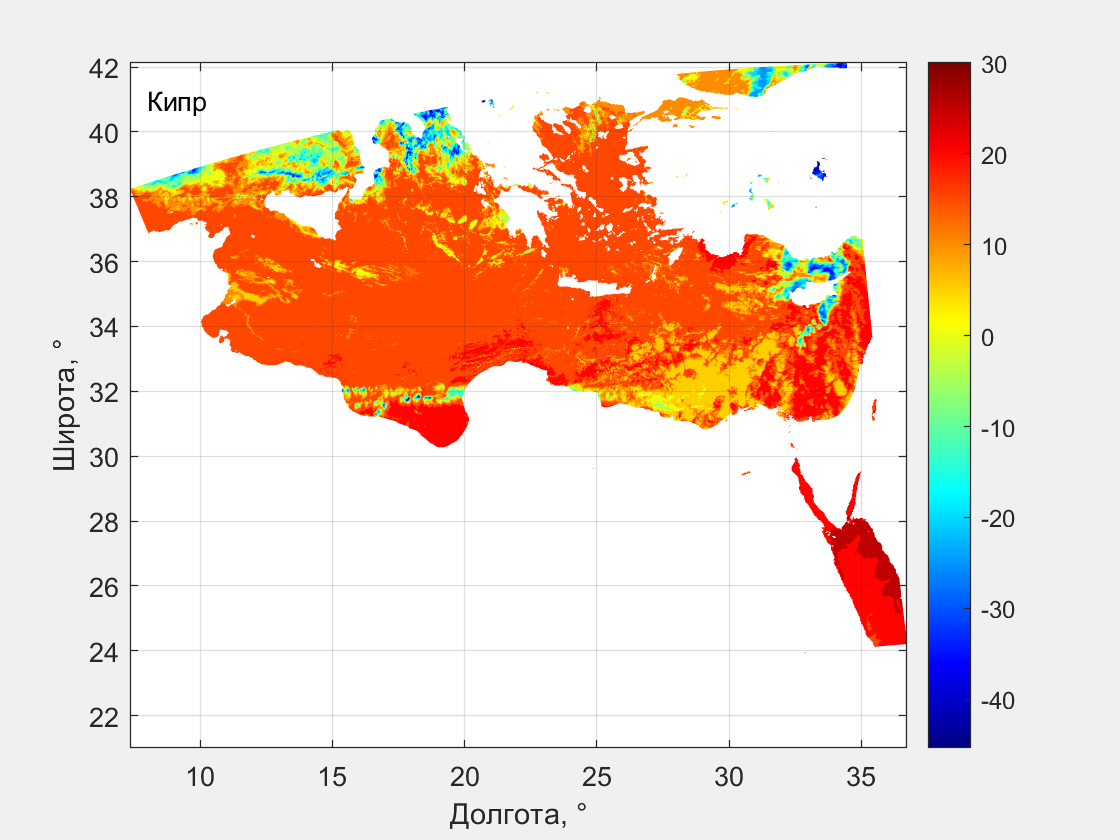

colormap jet

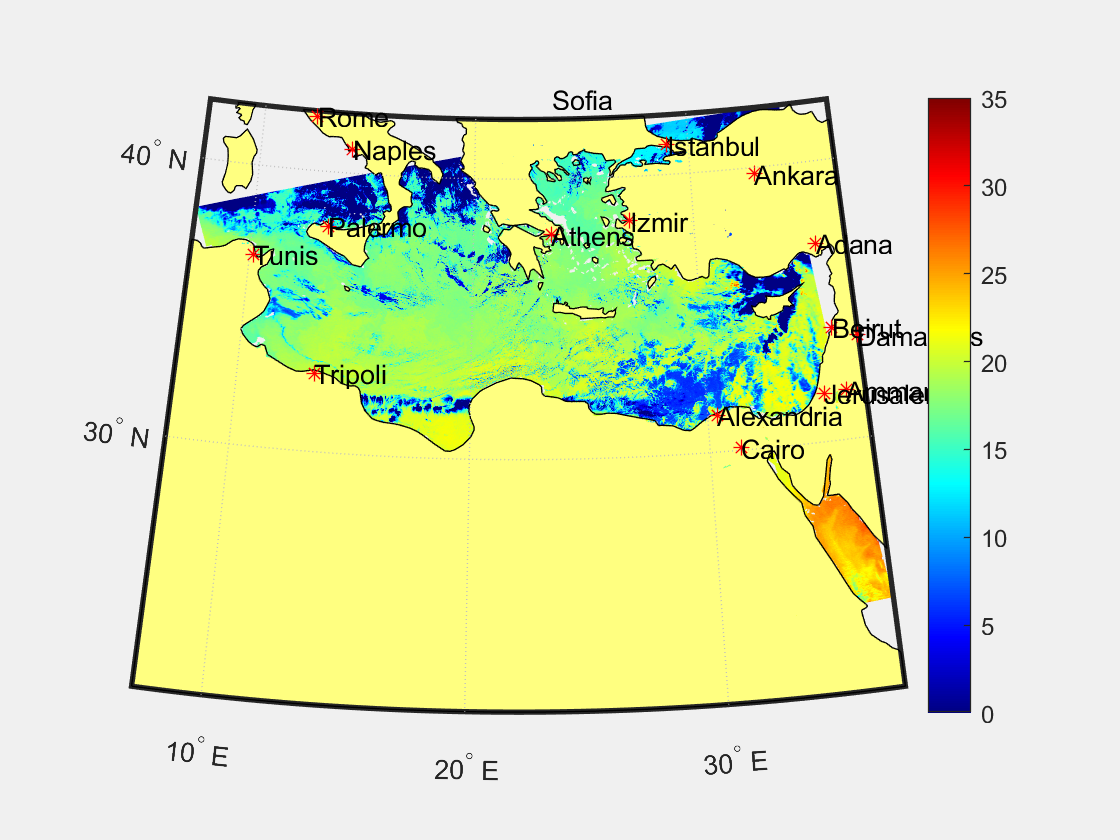


latmax = max(lat,[],'all');
latmin = min(lat,[],'all');
lonmax = max(lon,[],'all');
lonmin = min(lon,[],'all');

land = shaperead('landareas.shp',"UseGeoCoords",true);
cities = shaperead('worldcities.shp',"UseGeoCoords",true);

ax = worldmap([latmin, latmax],[lonmin, lonmax]);
geoshow(ax, land);
geoshow(ax, cities, 'Marker', '*','Tag','on');
geoshow(lat,lon,sst,'DisplayType','surface');
caxis([0 35]);
grid("on")
colormap('jet');
colorbar();
textm([cities.Lat],[cities.Lon],{cities.Name})